function PartStruct=deVchangeJMAGDesignerPartName4OuterRotor(PartStruct,app,MachineData)
    
    OnePoleAngle=360/MachineData.Poles;
    Model=app.GetCurrentModel;
    rotorStruct=PartStruct(findIsMatchedInStruct(PartStruct,'Name','Rotor'));
    MaxofMaxVertexRPos      =max([rotorStruct.VertexMaxRPos])    ;
    MaxofMaxVertexThetaPos  =max([rotorStruct.VertexMaxThetaPos]);
    MinofMinVertexRPos      =min([rotorStruct.VertexMinRPos])    ;

    isMax=ismember([rotorStruct.VertexMaxRPos],MaxofMaxVertexRPos);
    maxofMaxVertexRPartIndex=find(isMax);
    isMin=ismember([rotorStruct.VertexMinRPos],MinofMinVertexRPos);
    minofMinVertexRPartIndex=find(isMin);
    tolerance=1e-4;



case 0

외전형 SPMSM 생각 case0

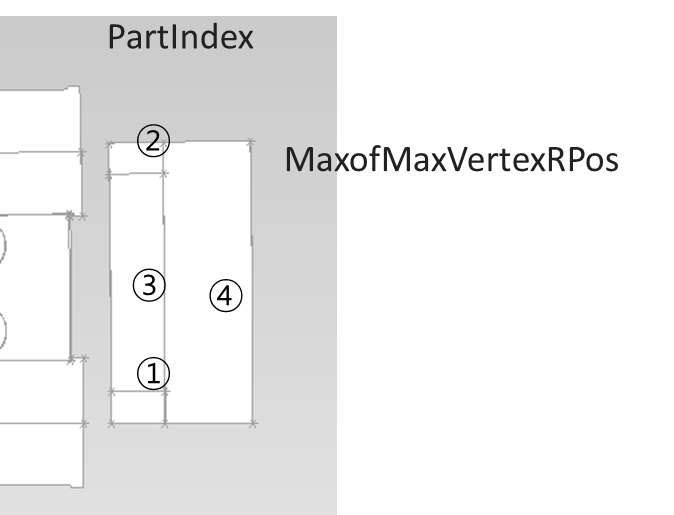

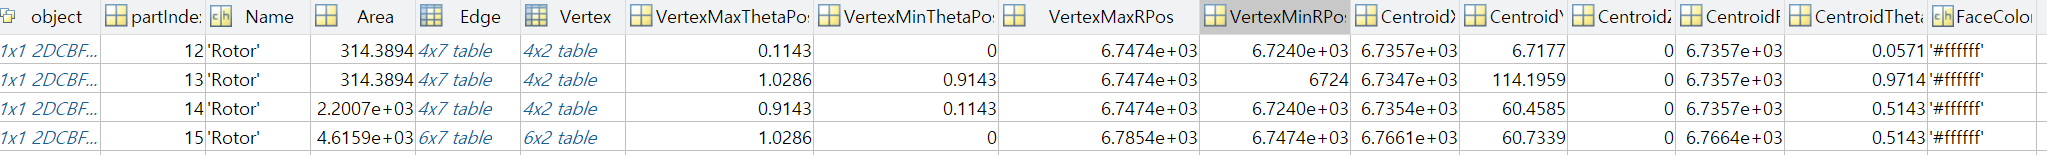

    % band가 없는걸 골라내기 위해서 rotorStruct.VertexMinRPos의
    % maxofMaxVertexRPartIndex의 MinRPos과 rotorStruct.VertexMinRPos의
    % MaxRPos이 일치하면 case 0
    % 일치하지않으면 case 10일꺼같은데
    % 자석은 어떻게 골라내지 ....
    % 분할 자석은? 
    % 
if all(maxofMaxVertexRPartIndex==minofMinVertexRPartIndex)
   caseNumber=99; 

elseif all(maxofMaxVertexRPartIndex~=minofMinVertexRPartIndex)
        % Position(:,4) 는 Radius

        MinROfOutMostPart   =min(rotorStruct(maxofMaxVertexRPartIndex).Vertex.VertexPosition(:,4));
        MaxRofInnerMostPart =max(rotorStruct(minofMinVertexRPartIndex(1)).Vertex.VertexPosition(:,4));
        isMatched = abs(MinROfOutMostPart- MaxRofInnerMostPart) < tolerance;
        if isMatched==1 && abs(rotorStruct(maxofMaxVertexRPartIndex).CentroidTheta-OnePoleAngle/2)<tolerance
          caseNumber=0;
          rotorStruct(maxofMaxVertexRPartIndex).Name             ='RotorCore';
        else
        caseNumber=2;
        end
end

case10

    % maxofMaxVertexRPartIndex의 MinRPos과 rotorStruct.VertexMinRPos의
    % MaxRPos이 일치하면 case 0
    % 일치하지않으면 case 10일꺼같은데

switch caseNumber
        case 0
            isRotorCore=ismember([PartStruct.partIndex],rotorStruct(maxofMaxVertexRPartIndex).partIndex);
            RotorCoreIndex=find(isRotorCore);
            PartStruct(RotorCoreIndex).Name             ='RotorCore';            
            if ~strcmp(PartStruct(RotorCoreIndex).object.GetName,'Magnet') &&  abs(PartStruct(RotorCoreIndex).CentroidTheta-OnePoleAngle/2)<tolerance
            PartStruct(RotorCoreIndex).object.SetName('RotorCore');
            end
        case 2
            isRotorCore=ismember([PartStruct.partIndex],rotorStruct(maxofMaxVertexRPartIndex).partIndex);
            RotorCoreIndex=find(isRotorCore);
            PartStruct(RotorCoreIndex).Name             ='RotorCore';   
            if ~strcmp(PartStruct(RotorCoreIndex).object.GetName,'Magnet') &&  abs(PartStruct(RotorCoreIndex).CentroidTheta-OnePoleAngle/2)<tolerance
            PartStruct(RotorCoreIndex).object.SetName('RotorCore');
            end

end

## 작업 & CenterPost

Rotor인 애들만 Angle 추출

MachineData의 중앙지점에서 대칭이고 중앙에서 최근접한 파트들의 면적과 다르면 AirBarrier로 설정 

case 0 자석 무분할 (CentroidTheta동일)

    % Angle=zeros(length(PartStruct) ,1);                         % Air Barrier 체크를 위한 각도
    % 
    % for partIndex4Squre = 1:length(PartStruct)
    %     if length(PartStruct(partIndex4Squre).Vertex.VertexIds) ~= 4 % Vertex 개수가 4개 아니면
    %         if (strcmp(PartStruct(Index4CheckCenterPost).Name,'Rotor') |strcmp(PartStruct(Index4CheckCenterPost).Name,'RotorAirBarrier'))
    %         Angle(partIndex4Squre, 1) = PartStruct(partIndex4Squre).CentroidTheta;
    %         Index4CheckCenterPost=partIndex4Squre;
    %         tolerance=1e-4;
    %         matchingIndices = find(arrayfun(@(x) max(abs(x.Area - PartStruct(Index4CheckCenterPost).Area)) <= tolerance, PartStruct));           
    %             % 사각형이 아니면서 Rotor 나  RotorAirBarrier인데  중앙에 위치하면서 같은 크기가 여러개여도 되는 구조물을 CenterPost 
    %             if length(matchingIndices)<4&&abs(RotorCoreCentroidTheta-PartStruct(Index4CheckCenterPost).CentroidTheta)<=tolerance                  
    %                    PartStruct(Index4CheckCenterPost).object.SetName('CenterAirPost');
    %                    PartStruct(Index4CheckCenterPost).Name='CenterAirPost';
    %             end
    %         end
    %     else
    %         if (strcmp(PartStruct(Index4CheckCenterPost).Name,'Rotor') |~strcmp(PartStruct(Index4CheckCenterPost).Name,'RotorCore'))&&length(matchingIndices)<4&&abs(RotorCoreCentroidTheta-PartStruct(Index4CheckCenterPost).CentroidTheta)<=tolerance                  
    % 
    %         Angle(partIndex4Squre, 1) = PartStruct(partIndex4Squre).CentroidTheta;                        % 길이가 4인 경우 NaN으로 설정
    %         end
    %     end
    % end

    for partIndex=1:length(PartStruct)
        if (~strcmp(PartStruct(partIndex).object.GetName, 'RotorCore') )&&strcmp(PartStruct(partIndex).object.GetName, 'Rotor') &&abs(PartStruct(partIndex).CentroidTheta-OnePoleAngle/2)<tolerance
            PartStruct(partIndex).object.SetName('Magnet');
            PartStruct(partIndex).Name='Magnet';
            
            isMagnet=ismember([rotorStruct.partIndex],PartStruct(partIndex).partIndex);
            rotorStruct(isMagnet).Name='Magnet';
        end
    end
end